# NR PDSCH Throughput

This reference simulation shows how to measure the physical downlink shared channel (PDSCH) throughput of a 5G New Radio (NR) link, as defined by the 3GPP NR standard. The example implements the PDSCH and downlink shared channel (DL-SCH). The transmitter model includes PDSCH demodulation reference signals (DM-RS) and PDSCH phase tracking reference signals (PT-RS). The example supports both clustered delay line (CDL) and tapped delay line (TDL) propagation channels. You can perform perfect or practical synchronization and channel estimation. To reduce the total simulation time, you can execute the SNR points in the SNR loop in parallel by using the Parallel Computing Toolbox™.

## Introduction

This example measures the PDSCH throughput of a 5G link, as defined by the 3GPP NR standard [ [1](about:blank<#13%3E) ], [ [2](about:blank<#13%3E) ], [ [3](about:blank<#13%3E) ], [ [4](about:blank<#13%3E) ].

The example models these 5G NR features:

- DL-SCH transport channel coding

- Multiple codewords, dependent on the number of layers

- PDSCH, PDSCH DM-RS, and PDSCH PT-RS generation

- Variable subcarrier spacing and frame numerologies (2^n * 15 kHz)

- Normal and extended cyclic prefix

- TDL and CDL propagation channel models

Other features of the simulation are:

- PDSCH subband precoding using SVD

- CP-OFDM modulation

- Slot wise and non slot wise PDSCH and DM-RS mapping

- Perfect or practical synchronization and channel estimation

- HARQ operation with 16 processes

- The example uses a single bandwidth part across the whole carrier

The figure shows the implemented processing chain. For clarity, the DM-RS and PT-RS generation are omitted.

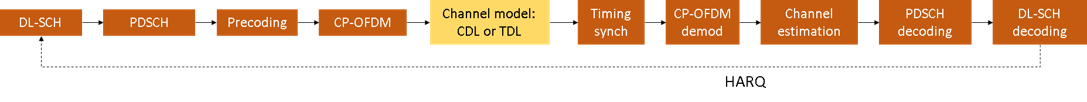

For a more detailed explanation of the steps implemented in this example, see [Model 5G NR Communication Links](docid:5g_gs#mw_b41487f2-4e53-412e-83ff-b77bd3984819) and [DL-SCH and PDSCH Transmit and Receive Processing Chain](docid:5g_gs#mw_5441cb0f-86ed-4038-8735-d0a50ea68f60).

This example supports both wideband and subband precoding. The precoding matrix is determined using SVD by averaging the channel estimate across all PDSCH PRBs in the allocation (wideband case) or in the subband.

To reduce the total simulation time, you can use the Parallel Computing Toolbox to execute the SNR points of the SNR loop in parallel.

## Simulation Length and SNR Points

Set the length of the simulation in terms of the number of 10ms frames. A large number of NFrames should be used to produce meaningful throughput results. Set the SNR points to simulate. The SNR for each layer is defined per RE, and it includes the effect of signal and noise across all antennas. For an explanation of the SNR definition that this example uses, see [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd).

simParameters = struct();       % Clear simParameters variable to contain all key simulation parameters
simParameters.NFrames = 2;      % Number of 10 ms frames
simParameters.SNRIn = [-5 0 5]; % SNR range (dB)

## Channel Estimator Configuration

The logical variable `PerfectChannelEstimator` controls channel estimation and synchronization behavior. When set to `true`, perfect channel estimation and synchronization is used. Otherwise, practical channel estimation and synchronization is used, based on the values of the received PDSCH DM-RS.

simParameters.PerfectChannelEstimator = true;

## Simulation Diagnostics

The variable `DisplaySimulationInformation` controls the display of simulation information such as the HARQ process ID used for each subframe. In case of CRC error, the value of the index to the RV sequence is also displayed.

simParameters.DisplaySimulationInformation = true;

The `DisplayDiagnostics` flag enables the plotting of the EVM per layer. This plot monitors the quality of the received signal after equalization. The EVM per layer figure shows:

- The EVM per layer per slot, which shows the EVM evolving with time.

- The EVM per layer per resource block, which shows the EVM in frequency.

This figure evolves with the simulation and is updated with each slot. Typically, low SNR or channel fades can result in decreased signal quality (high EVM). The channel affects each layer differently, therefore, the EVM values may differ across layers.

In some cases, some layers can have a much higher EVM than others. These low-quality layers can result in CRC errors. This behavior may be caused by low SNR or by using too many layers for the channel conditions. You can avoid this situation by a combination of higher SNR, lower number of layers, higher number of antennas, and more robust transmission (lower modulation scheme and target code rate).

simParameters.DisplayDiagnostics = false;

## Carrier and PDSCH Configuration

Set the key parameters of the simulation. These include:

- The bandwidth in resource blocks (12 subcarriers per resource block).

- Subcarrier spacing: 15, 30, 60, 120 (kHz)

- Cyclic prefix length: normal or extended

- Cell ID

- Number of transmit and receive antennas

A substructure containing the DL-SCH and PDSCH parameters is also specified. This includes:

- Target code rate

- Allocated resource blocks (PRBSet)

- Modulation scheme: 'QPSK', '16QAM', '64QAM', '256QAM'

- Number of layers

- PDSCH mapping type

- DM-RS configuration parameters

- PT-RS configuration parameters

Other simulation wide parameters are:

- Propagation channel model delay profile (TDL or CDL)

% Define parameter ranges
NSizeGridRange = [50, 106]; % Example range for 20 MHz bandwidth
SubcarrierSpacingRange = [15, 30, 60, 120, 240]; % Include all valid subcarrier spacing values
DelaySpreadRange = [50e-9, 500e-9]; % DelaySpread in seconds
MaximumDopplerShiftRange = [0, 30]; % MaximumDopplerShift in Hz

% Combine ranges into a single matrix
paramRanges = {NSizeGridRange, SubcarrierSpacingRange, DelaySpreadRange, MaximumDopplerShiftRange};

% Initialize particles
numParticles = 10; % Number of particles
[particlePopulation, particleVelocities] = initializeParticles(numParticles, paramRanges);


maxIterations = 15;
averageProcessingTimePerIteration = zeros(1, maxIterations); % To store average latency after each iteration
timestamps = datetime(zeros(1, maxIterations), 'ConvertFrom', 'datenum'); % To store timestamp
personalBestPositions = particlePopulation;
personalBestScores = inf(numParticles, 1);
globalBestPosition = [];
globalBestScore = inf;
% Initialize currentScore array
currentScore = zeros(1, numParticles);  % Assuming numParticles is defined earlier

for iter = 1:maxIterations
  % Iterate over each particle
    for particleIdx = 1:numParticles
    totalProcessingTime = 0;
    % Set waveform type and PDSCH numerology (SCS and CP type)
    simParameters.Carrier = nrCarrierConfig;         % Carrier resource grid configuration
    simParameters.Carrier.NSizeGrid = round(particlePopulation(particleIdx, 1));
    simParameters.Carrier.SubcarrierSpacing = particlePopulation(particleIdx, 2); 
    simParameters.Carrier.CyclicPrefix = 'Normal';   % 'Normal' or 'Extended' (Extended CP is relevant for 60 kHz SCS only)
    simParameters.Carrier.NCellID = 1;               % Cell identity
    
    % PDSCH/DL-SCH parameters
    simParameters.PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the BLER simulation
    simParameters.PDSCHExtension = struct();  % This structure is to hold additional simulation parameters for the DL-SCH and PDSCH
    
    % Define PDSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
    simParameters.PDSCH.PRBSet = 0:simParameters.Carrier.NSizeGrid-1;                 % PDSCH PRB allocation
    simParameters.PDSCH.SymbolAllocation = [0,simParameters.Carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PDSCH allocation
    simParameters.PDSCH.MappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))
    
    % Scrambling identifiers
    simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
    simParameters.PDSCH.RNTI = 1;
    
    % PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
    simParameters.PDSCH.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
    simParameters.PDSCH.VRBBundleSize = 4;
    
    % Define the number of transmission layers to be used
    simParameters.PDSCH.NumLayers = 1;           % Number of PDSCH transmission layers
    
    % Define codeword modulation and target coding rate
    % The number of codewords is directly dependent on the number of layers so ensure that
    % layers are set first before getting the codeword number
    if simParameters.PDSCH.NumCodewords > 1                             % Multicodeword transmission (when number of layers being > 4)
        simParameters.PDSCH.Modulation = {'16QAM','16QAM'};             % 'QPSK', '16QAM', '64QAM', '256QAM'
        simParameters.PDSCHExtension.TargetCodeRate = [490 490]/1024;   % Code rate used to calculate transport block sizes
    else
        simParameters.PDSCH.Modulation = '16QAM';                       % 'QPSK', '16QAM', '64QAM', '256QAM'
        simParameters.PDSCHExtension.TargetCodeRate = 490/1024;         % Code rate used to calculate transport block sizes
    end
    
    % DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
    simParameters.PDSCH.DMRS.DMRSPortSet = 0:simParameters.PDSCH.NumLayers-1; % DM-RS ports to use for the layers
    simParameters.PDSCH.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
    simParameters.PDSCH.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
    simParameters.PDSCH.DMRS.DMRSAdditionalPosition = 2; % Additional DM-RS symbol positions (max range 0...3)
    simParameters.PDSCH.DMRS.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
    simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;% Number of CDM groups without data
    simParameters.PDSCH.DMRS.NIDNSCID = 1;               % Scrambling identity (0...65535)
    simParameters.PDSCH.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)
    
    % PT-RS configuration (TS 38.211 Section 7.4.1.2)
    simParameters.PDSCH.EnablePTRS = 0;                  % Enable or disable PT-RS (1 or 0)
    simParameters.PDSCH.PTRS.TimeDensity = 1;            % PT-RS time density (L_PT-RS) (1, 2, 4)
    simParameters.PDSCH.PTRS.FrequencyDensity = 2;       % PT-RS frequency density (K_PT-RS) (2 or 4)
    simParameters.PDSCH.PTRS.REOffset = '00';            % PT-RS resource element offset ('00', '01', '10', '11')
    simParameters.PDSCH.PTRS.PTRSPortSet = [];           % PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lower DM-RS port number
    
    % Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
    simParameters.PDSCH.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
    simParameters.PDSCH.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
    simParameters.PDSCH.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources
    
    % Additional simulation and DL-SCH related parameters
    %
    % PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
    simParameters.PDSCHExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"
    %
    % HARQ process and rate matching/TBS parameters
    simParameters.PDSCHExtension.XOverhead = 6*simParameters.PDSCH.EnablePTRS; % Set PDSCH rate matching overhead for TBS (Xoh) to 6 when PT-RS is enabled, otherwise 0
    simParameters.PDSCHExtension.NHARQProcesses = 16;    % Number of parallel HARQ processes to use
    simParameters.PDSCHExtension.EnableHARQ = true;      % Enable retransmissions for each process, using RV sequence [0,2,3,1]
    
    % LDPC decoder parameters
    % Available algorithms: 'Belief propagation', 'Layered belief propagation', 'Normalized min-sum', 'Offset min-sum'
    simParameters.PDSCHExtension.LDPCDecodingAlgorithm = 'Normalized min-sum';
    simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;
    
    % Define the overall transmission antenna geometry at end-points
    % If using a CDL propagation channel then the integer number of antenna elements is
    % turned into an antenna panel configured when the channel model object is created
    simParameters.NTxAnts = 8;                        % Number of PDSCH transmission antennas (1,2,4,8,16,32,64,128,256,512,1024) >= NumLayers
    if simParameters.PDSCH.NumCodewords > 1           % Multi-codeword transmission
        simParameters.NRxAnts = 8;                    % Number of UE receive antennas (even number >= NumLayers)
    else
        simParameters.NRxAnts = 2;                    % Number of UE receive antennas (1 or even number >= NumLayers)
    end
    
    % Define the general CDL/TDL propagation channel parameters
    simParameters.DelayProfile = 'CDL-C';   % Use CDL-C model (Urban macrocell model)
    simParameters.DelaySpread = 300e-9;
    simParameters.MaximumDopplerShift = particlePopulation(particleIdx, 4);
    
    % Cross-check the PDSCH layering against the channel geometry
    validateNumLayers(simParameters);

The simulation relies on various pieces of information about the baseband waveform, such as sample rate.

    waveformInfo = nrOFDMInfo(simParameters.Carrier); % Get information about the baseband waveform after OFDM modulation step

## Propagation Channel Model Construction

Create the channel model object for the simulation. Both CDL and TDL channel models are supported [ [5](about:blank<#13%3E) ].

    % Constructed the CDL or TDL channel model object
    if contains(simParameters.DelayProfile,'CDL','IgnoreCase',true)
        
        channel = nrCDLChannel; % CDL channel object
        
        % Turn the number of antennas into antenna panel array layouts. If
        % NTxAnts is not one of (1,2,4,8,16,32,64,128,256,512,1024), its value
        % is rounded up to the nearest value in the set. If NRxAnts is not 1 or
        % even, its value is rounded up to the nearest even number.
        channel = hArrayGeometry(channel,simParameters.NTxAnts,simParameters.NRxAnts);
        simParameters.NTxAnts = prod(channel.TransmitAntennaArray.Size);
        simParameters.NRxAnts = prod(channel.ReceiveAntennaArray.Size);
    else
        channel = nrTDLChannel; % TDL channel object
        
        % Set the channel geometry
        channel.NumTransmitAntennas = simParameters.NTxAnts;
        channel.NumReceiveAntennas = simParameters.NRxAnts;
    end
    
    % Assign simulation channel parameters and waveform sample rate to the object
    channel.DelayProfile = simParameters.DelayProfile;
    channel.DelaySpread = simParameters.DelaySpread;
    channel.MaximumDopplerShift = simParameters.MaximumDopplerShift;
    channel.SampleRate = waveformInfo.SampleRate;

Get the maximum number of delayed samples by a channel multipath component. This is calculated from the channel path with the largest delay and the implementation delay of the channel filter. This is required later to flush the channel filter to obtain the received signal.

    chInfo = info(channel);
    maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + chInfo.ChannelFilterDelay;

## Processing Loop

To determine the throughput at each SNR point, analyze the PDSCH data per transmission instance using the following steps:

- *Update current HARQ process.* Check the transmission status for the given HARQ process to determine whether a retransmission is required. If that is not the case then generate new data.

- *Resource grid generation.* Perform channel coding by calling the [nrDLSCH](docid:5g_ref#mw_sysobj_nrDLSCH) System object. The object operates on the input transport block and keeps an internal copy of the transport block in case a retransmission is required. Modulate the coded bits on the PDSCH by using the [nrPDSCH](docid:5g_ref#mw_function_nrPDSCH) function. Then apply precoding to the resulting signal.

- *Waveform generation.* OFDM modulate the generated grid.

- *Noisy channel modeling.* Pass the waveform through a CDL or TDL fading channel. Add AWGN. For an explanation of the SNR definition that this example uses, see [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd).

- *Perform synchronization and OFDM demodulation.* For perfect synchronization, reconstruct the channel impulse response to synchronize the received waveform. For practical synchronization, correlate the received waveform with the PDSCH DM-RS. Then OFDM demodulate the synchronized signal.

- *Perform channel estimation.* For perfect channel estimation, reconstruct the channel impulse response and perform OFDM demodulation. For practical channel estimation, use the PDSCH DM-RS.

- *Perform equalization and CPE compensation.* MMSE equalize the estimated channel. Estimate the common phase error (CPE) by using the PT-RS symbols, then correct the error in each OFDM symbol within the range of reference PT-RS OFDM symbols.

- *Precoding matrix calculation.* Generate the precoding matrix W for the next transmission by using singular value decomposition (SVD).

- *Decode the PDSCH.* To obtain an estimate of the received codewords, demodulate and descramble the recovered PDSCH symbols for all transmit and receive antenna pairs, along with a noise estimate, by using the [nrPDSCHDecode](docid:5g_ref#mw_function_nrPDSCHDecode) function.

- *Decode the downlink shared channel (DL-SCH) and update HARQ process with the block CRC error.* Pass the vector of decoded soft bits to the [nrDLSCHDecoder](docid:5g_ref#mw_sysobj_nrDLSCHDecoder) System object. The object decodes the codeword and returns the block CRC error used to determine the throughput of the system.

    % Array to store the maximum throughput for all SNR points
    maxThroughput = zeros(length(simParameters.SNRIn),1);
    % Array to store the simulation throughput for all SNR points
    simThroughput = zeros(length(simParameters.SNRIn),1);
    
    % Set up redundancy version (RV) sequence for all HARQ processes
    if simParameters.PDSCHExtension.EnableHARQ
        % In the final report of RAN WG1 meeting #91 (R1-1719301), it was
        % observed in R1-1717405 that if performance is the priority, [0 2 3 1]
        % should be used. If self-decodability is the priority, it should be
        % taken into account that the upper limit of the code rate at which
        % each RV is self-decodable is in the following order: 0>3>2>1
        rvSeq = [0 2 3 1];
    else
        % HARQ disabled - single transmission with RV=0, no retransmissions
        rvSeq = 0;
    end
    
    % Create DL-SCH encoder system object to perform transport channel encoding
    encodeDLSCH = nrDLSCH;
    encodeDLSCH.MultipleHARQProcesses = true;
    encodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
    
    % Create DL-SCH decoder system object to perform transport channel decoding
    % Use layered belief propagation for LDPC decoding, with half the number of
    % iterations as compared to the default for belief propagation decoding
    decodeDLSCH = nrDLSCHDecoder;
    decodeDLSCH.MultipleHARQProcesses = true;
    decodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
    decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
    decodeDLSCH.MaximumLDPCIterationCount = simParameters.PDSCHExtension.MaximumLDPCIterationCount;
    
    for snrIdx = 1:numel(simParameters.SNRIn)      % comment out for parallel computing
        % parfor snrIdx = 1:numel(simParameters.SNRIn) % uncomment for parallel computing
        % To reduce the total simulation time, you can execute this loop in
        % parallel by using the Parallel Computing Toolbox. Comment out the 'for'
        % statement and uncomment the 'parfor' statement. If the Parallel Computing
        % Toolbox is not installed, 'parfor' defaults to normal 'for' statement.
        % Because parfor-loop iterations are executed in parallel in a
        % nondeterministic order, the simulation information displayed for each SNR
        % point can be intertwined. To switch off simulation information display,
        % set the 'displaySimulationInformation' variable above to false
        
        % Reset the random number generator so that each SNR point will
        % experience the same noise realization
        rng('default');
        
        % Take full copies of the simulation-level parameter structures so that they are not
        % PCT broadcast variables when using parfor
        simLocal = simParameters;
        waveinfoLocal = waveformInfo;
        
        % Take copies of channel-level parameters to simplify subsequent parameter referencing
        carrier = simLocal.Carrier;
        pdsch = simLocal.PDSCH;
        pdschextra = simLocal.PDSCHExtension;
        decodeDLSCHLocal = decodeDLSCH;  % Copy of the decoder handle to help PCT classification of variable
        decodeDLSCHLocal.reset();        % Reset decoder at the start of each SNR point
        pathFilters = [];
        
        % Prepare simulation for new SNR point
        SNRdB = simLocal.SNRIn(snrIdx);
        fprintf('\nSimulating transmission scheme 1 (%dx%d) and SCS=%dkHz with %s channel at %gdB SNR for %d 10ms frame(s)\n', ...
            simLocal.NTxAnts,simLocal.NRxAnts,carrier.SubcarrierSpacing, ...
            simLocal.DelayProfile,SNRdB,simLocal.NFrames);
        
        % Specify the fixed order in which we cycle through the HARQ process IDs
        harqSequence = 0:pdschextra.NHARQProcesses-1;
        
        % Initialize the state of all HARQ processes
        harqEntity = HARQEntity(harqSequence,rvSeq,pdsch.NumCodewords);
        
        % Reset the channel so that each SNR point will experience the same
        % channel realization
        reset(channel);
        
        % Total number of slots in the simulation period
        NSlots = simLocal.NFrames * carrier.SlotsPerFrame;
        
        % Obtain a precoding matrix (wtx) to be used in the transmission of the
        % first transport block
        estChannelGrid = getInitialChannelEstimate(carrier,simLocal.NTxAnts,channel);
        newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
        
        % Timing offset, updated in every slot for perfect synchronization and
        % when the correlation is strong for practical synchronization
        offset = 0;
        
        % Loop over the entire waveform length
        for nslot = 0:NSlots-1
            
            % Update the carrier slot numbers for new slot
            carrier.NSlot = nslot;
            
            % Calculate the transport block sizes for the transmission in the slot
            [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
            trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);
            
            % HARQ processing
            for cwIdx = 1:pdsch.NumCodewords
                % If new data for current process and codeword then create a new DL-SCH transport block
                if harqEntity.NewData(cwIdx)
                    trBlk = randi([0 1],trBlkSizes(cwIdx),1);
                    setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity.HARQProcessID);
                    % If new data because of previous RV sequence time out then flush decoder soft buffer explicitly
                    if harqEntity.SequenceTimeout(cwIdx)
                        resetSoftBuffer(decodeDLSCHLocal,cwIdx-1,harqEntity.HARQProcessID);
                    end
                end
            end
            
            % Encode the DL-SCH transport blocks
            codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
                pdschIndicesInfo.G,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
            
            % Get precoding matrix (wtx) calculated in previous slot
            wtx = newWtx;
            
            % Create resource grid for a slot
            pdschGrid = nrResourceGrid(carrier,simLocal.NTxAnts);
            
            % PDSCH modulation and precoding
            pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
            [pdschAntSymbols,pdschAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,pdschSymbols,pdschIndices,wtx);
            
            % PDSCH mapping in grid associated with PDSCH transmission period
            pdschGrid(pdschAntIndices) = pdschAntSymbols;
            
            % PDSCH DM-RS precoding and mapping
            dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
            dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
            [dmrsAntSymbols,dmrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,dmrsSymbols,dmrsIndices,wtx);
            pdschGrid(dmrsAntIndices) = dmrsAntSymbols;
            
            % PDSCH PT-RS precoding and mapping
            ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
            ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
            [ptrsAntSymbols,ptrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,ptrsSymbols,ptrsIndices,wtx);
            pdschGrid(ptrsAntIndices) = ptrsAntSymbols;
            
            % OFDM modulation
            txWaveform = nrOFDMModulate(carrier,pdschGrid);
            
            % Pass data through channel model. Append zeros at the end of the
            % transmitted waveform to flush channel content. These zeros take
            % into account any delay introduced in the channel. This is a mix
            % of multipath delay and implementation delay. This value may
            % change depending on the sampling rate, delay profile and delay
            % spread
            txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
            [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
            
            % Add AWGN to the received time domain waveform
            % Normalize noise power by the IFFT size used in OFDM modulation,
            % as the OFDM modulator applies this normalization to the
            % transmitted waveform. Also normalize by the number of receive
            % antennas, as the channel model applies this normalization to the
            % received waveform, by default
            SNR = 10^(SNRdB/10);
            N0 = 1/sqrt(2.0*simLocal.NRxAnts*double(waveinfoLocal.Nfft)*SNR);
            noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
            rxWaveform = rxWaveform + noise;
            
            if (simLocal.PerfectChannelEstimator)
                % Perfect synchronization. Use information provided by the
                % channel to find the strongest multipath component
                pathFilters = getPathFilters(channel);
                [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
            else
                % Practical synchronization. Correlate the received waveform
                % with the PDSCH DM-RS to give timing offset estimate 't' and
                % correlation magnitude 'mag'. The function
                % hSkipWeakTimingOffset is used to update the receiver timing
                % offset. If the correlation peak in 'mag' is weak, the current
                % timing estimate 't' is ignored and the previous estimate
                % 'offset' is used
                [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
                offset = hSkipWeakTimingOffset(offset,t,mag);
                % Display a warning if the estimated timing offset exceeds the
                % maximum channel delay
                if offset > maxChDelay
                    warning(['Estimated timing offset (%d) is greater than the maximum channel delay (%d).' ...
                        ' This will result in a decoding failure. This may be caused by low SNR,' ...
                        ' or not enough DM-RS symbols to synchronize successfully.'],offset,maxChDelay);
                end
            end
            rxWaveform = rxWaveform(1+offset:end,:);
            
            % Perform OFDM demodulation on the received data to recreate the
            % resource grid, including padding in the event that practical
            % synchronization results in an incomplete slot being demodulated
            rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
            [K,L,R] = size(rxGrid);
            if (L < carrier.SymbolsPerSlot)
                rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
            end
            
            if (simLocal.PerfectChannelEstimator)
                % Perfect channel estimation, using the value of the path gains
                % provided by the channel. This channel estimate does not
                % include the effect of transmitter precoding
                estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
                
                % Get perfect noise estimate (from the noise realization)
                noiseGrid = nrOFDMDemodulate(carrier,noise(1+offset:end ,:));
                noiseEst = var(noiseGrid(:));
                
                % Get precoding matrix for next slot
                newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
                
                % Get PDSCH resource elements from the received grid and
                % channel estimate
                [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
                
                % Apply precoding to channel estimate
                pdschHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,pdschHest,pdschHestIndices,permute(wtx,[2 1 3]));
            else
                % Practical channel estimation between the received grid and
                % each transmission layer, using the PDSCH DM-RS for each
                % layer. This channel estimate includes the effect of
                % transmitter precoding
                [estChannelGrid,noiseEst] = nrChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);
                
                % Get PDSCH resource elements from the received grid and
                % channel estimate
                [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
                
                % Remove precoding from estChannelGrid prior to precoding
                % matrix calculation
                estChannelGridPorts = precodeChannelEstimate(carrier,estChannelGrid,conj(wtx));
                
                % Get precoding matrix for next slot
                newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGridPorts,pdschextra.PRGBundleSize);
            end
            
            % Equalization
            [pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);
            
            % Common phase error (CPE) compensation
            if ~isempty(ptrsIndices)
                % Initialize temporary grid to store equalized symbols
                tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);
                
                % Extract PT-RS symbols from received grid and estimated
                % channel grid
                [ptrsRx,ptrsHest,~,~,ptrsHestIndices,ptrsLayerIndices] = nrExtractResources(ptrsIndices,rxGrid,estChannelGrid,tempGrid);
                
                if (simLocal.PerfectChannelEstimator)
                    % Apply precoding to channel estimate
                    ptrsHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,ptrsHest,ptrsHestIndices,permute(wtx,[2 1 3]));
                end
                
                % Equalize PT-RS symbols and map them to tempGrid
                ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
                tempGrid(ptrsLayerIndices) = ptrsEq;
                
                % Estimate the residual channel at the PT-RS locations in
                % tempGrid
                cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);
                
                % Sum estimates across subcarriers, receive antennas, and
                % layers. Then, get the CPE by taking the angle of the
                % resultant sum
                cpe = angle(sum(cpe,[1 3 4]));
                
                % Map the equalized PDSCH symbols to tempGrid
                tempGrid(pdschIndices) = pdschEq;
                
                % Correct CPE in each OFDM symbol within the range of reference
                % PT-RS OFDM symbols
                symLoc = pdschIndicesInfo.PTRSSymbolSet(1)+1:pdschIndicesInfo.PTRSSymbolSet(end)+1;
                tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));
                
                % Extract PDSCH symbols
                pdschEq = tempGrid(pdschIndices);
            end
            
            % Decode PDSCH physical channel
            [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);
            
            % Display EVM per layer, per slot and per RB
            if (simLocal.DisplayDiagnostics)
                plotLayerEVM(NSlots,nslot,pdsch,size(pdschGrid),pdschIndices,pdschSymbols,pdschEq);
            end
            
            % Scale LLRs by CSI
            csi = nrLayerDemap(csi); % CSI layer demapping
            for cwIdx = 1:pdsch.NumCodewords
                Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
                csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);                 % expand by each bit per symbol
                dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale by CSI
            end
            
            % Decode the DL-SCH transport channel
            decodeDLSCHLocal.TransportBlockLength = trBlkSizes;
            [decbits,blkerr] = decodeDLSCHLocal(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
            
            % Store values to calculate throughput
            simThroughput(snrIdx) = simThroughput(snrIdx) + sum(~blkerr .* trBlkSizes);
            maxThroughput(snrIdx) = maxThroughput(snrIdx) + sum(trBlkSizes);
            
            % Update current process with CRC error and advance to next process
            procstatus = updateAndAdvance(harqEntity,blkerr,trBlkSizes,pdschIndicesInfo.G);
            if (simLocal.DisplaySimulationInformation)
                fprintf('\n(%3.2f%%) NSlot=%d, %s',100*(nslot+1)/NSlots,nslot,procstatus);
            end
            
     
        
        end

                
        % Display the results dynamically in the command window
        if (simLocal.DisplaySimulationInformation)
            fprintf('\n');
        end
        fprintf('\nThroughput(Mbps) for %d frame(s) = %.4f\n',simLocal.NFrames,1e-6*simThroughput(snrIdx)/(simLocal.NFrames*10e-3));
        fprintf('Throughput(%%) for %d frame(s) = %.4f\n',simLocal.NFrames,simThroughput(snrIdx)*100/maxThroughput(snrIdx));
    end


Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481386).


Throughput(Mbps) for 2 frame(s) = 243.6720


Throughput(%) for 2 frame(s) = 97.5000



Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 0dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481386).


Throughput(Mbps) for 2 frame(s) = 249.9200


Throughput(%) for 2 frame(s) = 100.0000



Simulating transmission scheme 1 (8x2) and SCS=120kHz with CDL-C channel at 5dB SNR for 2 10ms frame(s)



(0.62%) NSlot=0, HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.25%) NSlot=1, HARQ Proc 1: CW0: Initial transmission passed (RV=0,CR=0.481386).
(1.88%) NSlot=2, HARQ Proc 2: CW0: Initial transmission passed (RV=0,CR=0.481386).
(2.50%) NSlot=3, HARQ Proc 3: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.12%) NSlot=4, HARQ Proc 4: CW0: Initial transmission passed (RV=0,CR=0.481386).
(3.75%) NSlot=5, HARQ Proc 5: CW0: Initial transmission passed (RV=0,CR=0.481386).
(4.38%) NSlot=6, HARQ Proc 6: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.00%) NSlot=7, HARQ Proc 7: CW0: Initial transmission passed (RV=0,CR=0.481386).
(5.62%) NSlot=8, HARQ Proc 8: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.25%) NSlot=9, HARQ Proc 9: CW0: Initial transmission passed (RV=0,CR=0.481386).
(6.88%) NSlot=10, HARQ Proc 10: CW0: Initial transmission passed (RV=0,CR=0.481386).
(7.50%) NSlot=11, HARQ Proc 11: CW0: Initial transmission passed (RV=0,CR=0.481386).


Throughput(Mbps) for 2 frame(s) = 249.9200


Throughput(%) for 2 frame(s) = 100.0000



Simulating transmission scheme 1 (8x2) and SCS=15kHz with CDL-C channel at -5dB SNR for 2 10ms frame(s)


Error using ldpcEncode
Expected the second input argument to be an ldpcEncoderConfig object.

Error in nr5g.internal.ldpc.encode (line 97)
    codewords = ldpcEncode(infoBits,encoderCfg{bgn,setIdx,Zc});

Error in nrLDPCEncode (line 78)
    outCBall = nr5g.internal.ld

    averageThroughput = mean(simThroughput); % Calculate the average throughput across all SNR points
    averageThroughputPerIteration(iter) = averageThroughput; % Store this value for the current iteration
    fprintf('Average Throughput for iteration %d: %.4f (Mbps)\n', iter, averageThroughput);
    % Store the results
    currentScore(particleIdx) = averageThroughput; % Assuming higher throughput is better

    % Update personal and global bests
    for i = 1:numParticles
        if currentScore(i) < personalBestScores(i)
            personalBestScores(i) = currentScore(i);
            personalBestPositions(i, :) = particlePopulation(i, :);
        end
        if currentScore(i) < globalBestScore
            globalBestScore = currentScore(i);
            globalBestPosition = particlePopulation(i, :);
        end
    end
   
  end

    % Update particle positions and velocities
    [particlePopulation, particleVelocities] = UpdateParticlePositions(particlePopulation, particleVelocities, personalBestPositions, globalBestPosition, paramRanges);


end

figure;
plot(1:maxIterations, averageThroughputPerIteration, '-o');
xlabel('Iteration');
ylabel('Average Throughput (Mbps)');
title('Throughput Improvement per Iteration');
grid on;

## Results

Display the measured throughput. This is calculated as the percentage of the maximum possible throughput of the link given the available resources for data transmission.

% Find and output the best parameter set
figure;
plot(simParameters.SNRIn,simThroughput*100./maxThroughput,'o-.')
xlabel('SNR (dB)'); ylabel('Throughput (%)'); grid on;
title(sprintf('%s (%dx%d) / NRB=%d / SCS=%dkHz', ...
    simParameters.DelayProfile,simParameters.NTxAnts,simParameters.NRxAnts, ...
    simParameters.Carrier.NSizeGrid,simParameters.Carrier.SubcarrierSpacing));

% Bundle key parameters and results into a combined structure for recording
simResults.simParameters = simParameters;
simResults.simThroughput = simThroughput;
simResults.maxThroughput = maxThroughput;

The figure below shows throughput results obtained simulating 10000 subframes (`NFrames = 1000`, `SNRIn = -18:2:16`).

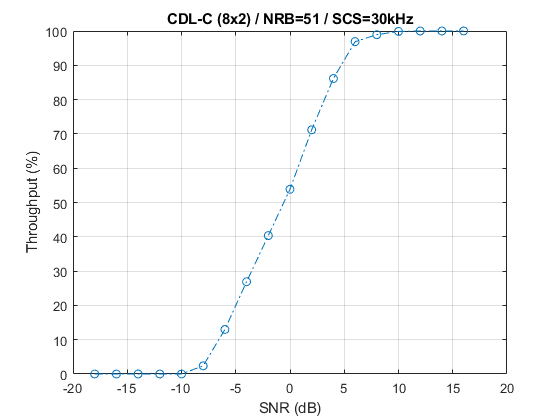

## Selected Bibliography

- 3GPP TS 38.211. "NR; Physical channels and modulation." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TS 38.212. "NR; Multiplexing and channel coding." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TS 38.213. "NR; Physical layer procedures for control." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TS 38.214. "NR; Physical layer procedures for data." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

- 3GPP TR 38.901. "Study on channel model for frequencies from 0.5 to 100 GHz." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

## Local Functions

function validateNumLayers(simParameters)
% Validate the number of layers, relative to the antenna geometry

numlayers = simParameters.PDSCH.NumLayers;
ntxants = simParameters.NTxAnts;
nrxants = simParameters.NRxAnts;
antennaDescription = sprintf('min(NTxAnts,NRxAnts) = min(%d,%d) = %d',ntxants,nrxants,min(ntxants,nrxants));
if numlayers > min(ntxants,nrxants)
    error('The number of layers (%d) must satisfy NumLayers <= %s', ...
        numlayers,antennaDescription);
end

% Display a warning if the maximum possible rank of the channel equals
% the number of layers
if (numlayers > 2) && (numlayers == min(ntxants,nrxants))
    warning(['The maximum possible rank of the channel, given by %s, is equal to NumLayers (%d).' ...
        ' This may result in a decoding failure under some channel conditions.' ...
        ' Try decreasing the number of layers or increasing the channel rank' ...
        ' (use more transmit or receive antennas).'],antennaDescription,numlayers); %#ok<SPWRN>
end

end

function estChannelGrid = getInitialChannelEstimate(carrier,nTxAnts,propchannel)
% Obtain channel estimate before first transmission. This can be used to
% obtain a precoding matrix for the first slot.

ofdmInfo = nrOFDMInfo(carrier);

chInfo = info(propchannel);
maxChDelay = ceil(max(chInfo.PathDelays*propchannel.SampleRate)) + chInfo.ChannelFilterDelay;

% Temporary waveform (only needed for the sizes)
tmpWaveform = zeros((ofdmInfo.SampleRate/1000/carrier.SlotsPerSubframe)+maxChDelay,nTxAnts);

% Filter through channel
[~,pathGains,sampleTimes] = propchannel(tmpWaveform);

% Perfect timing synch
pathFilters = getPathFilters(propchannel);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);

% Perfect channel estimate
estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

end

function wtx = getPrecodingMatrix(carrier,pdsch,hestGrid,prgbundlesize)
% Calculate precoding matrices for all PRGs in the carrier that overlap
% with the PDSCH allocation

% Maximum CRB addressed by carrier grid
maxCRB = carrier.NStartGrid + carrier.NSizeGrid - 1;

% PRG size
if nargin==4 && ~isempty(prgbundlesize)
    Pd_BWP = prgbundlesize;
else
    Pd_BWP = maxCRB + 1;
end

% PRG numbers (1-based) for each RB in the carrier grid
NPRG = ceil((maxCRB + 1) / Pd_BWP);
prgset = repmat((1:NPRG),Pd_BWP,1);
prgset = prgset(carrier.NStartGrid + (1:carrier.NSizeGrid).');

[~,~,R,P] = size(hestGrid);
wtx = zeros([pdsch.NumLayers P NPRG]);
for i = 1:NPRG
    
    % Subcarrier indices within current PRG and within the PDSCH
    % allocation
    thisPRG = find(prgset==i) - 1;
    thisPRG = intersect(thisPRG,pdsch.PRBSet(:),'rows');
    prgSc = (1:12)' + 12*thisPRG';
    prgSc = prgSc(:);
    
    if (~isempty(prgSc))
        
        % Average channel estimate in PRG
        estAllocGrid = hestGrid(prgSc,:,:,:);
        Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
        
        % SVD decomposition
        [~,~,V] = svd(Hest);
        wtx(:,:,i) = V(:,1:pdsch.NumLayers).';
        
    end
    
end

wtx = wtx / sqrt(pdsch.NumLayers); % Normalize by NumLayers

end

function estChannelGrid = precodeChannelEstimate(carrier,estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate

[K,L,R,P] = size(estChannelGrid);
estChannelGrid = reshape(estChannelGrid,[K*L R P]);
estChannelGrid = hPRGPrecode([K L R P],carrier.NStartGrid,estChannelGrid,reshape(1:numel(estChannelGrid),[K*L R P]),W);
estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end

function plotLayerEVM(NSlots,nslot,pdsch,siz,pdschIndices,pdschSymbols,pdschEq)
% Plot EVM information

persistent slotEVM;
persistent rbEVM
persistent evmPerSlot;

if (nslot==0)
    slotEVM = comm.EVM;
    rbEVM = comm.EVM;
    evmPerSlot = NaN(NSlots,pdsch.NumLayers);
    figure;
end
evmPerSlot(nslot+1,:) = slotEVM(pdschSymbols,pdschEq);
subplot(2,1,1);
plot(0:(NSlots-1),evmPerSlot,'o-');
xlabel('Slot number');
ylabel('EVM (%)');
legend("layer " + (1:pdsch.NumLayers),'Location','EastOutside');
title('EVM per layer per slot');

subplot(2,1,2);
[k,~,p] = ind2sub(siz,pdschIndices);
rbsubs = floor((k-1) / 12);
NRB = siz(1) / 12;
evmPerRB = NaN(NRB,pdsch.NumLayers);
for nu = 1:pdsch.NumLayers
    for rb = unique(rbsubs).'
        this = (rbsubs==rb & p==nu);
        evmPerRB(rb+1,nu) = rbEVM(pdschSymbols(this),pdschEq(this));
    end
end
plot(0:(NRB-1),evmPerRB,'x-');
xlabel('Resource block');
ylabel('EVM (%)');
legend("layer " + (1:pdsch.NumLayers),'Location','EastOutside');
title(['EVM per layer per resource block, slot #' num2str(nslot)]);

drawnow;

end

*Copyright 2017-2022 The MathWorks, Inc.*